folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Optimal_control_theory\lab5\tex\images\";

parallel.gpu.enableCUDAForwardCompatibility(true);
gpuDevice;

A = [0 1; -9 -2];
B = [8; 4];
C = [1 0];
G = eye(2);

W = [7 4; 4 5];
V = 4;

x0 = [1; 0];
xhat0 = [0; 0];

Lw = chol(W, 'lower');

[P, ~, ~] = care(A.', C.', G*W*G.', V);
L = P*C.'/V;

Jopt = trace(P);

N = 10000000;
T = 10;
dt = 0.001;

t = (0:0.01:T)';
step = round(0.01/dt);

F = gpuArray(single(A - L*C));
H = gpuArray(single([G*Lw, -L*sqrt(V)]));

Fd = gpuArray(single(eye(2) + dt*(A - L*C)));

E = repmat(gpuArray(single(x0-xhat0)), 1, N);

Jgpu = gpuArray.zeros(length(t), 1, 'single');
e1gpu = gpuArray.zeros(length(t), 1, 'single');
e2gpu = gpuArray.zeros(length(t), 1, 'single');

gpurng(42);

Jgpu(1) = mean(sum(E.^2, 1));
e1gpu(1) = E(1,1);
e2gpu(1) = E(2,1);

tic;

for k = 1:round(T/dt)
    z = randn(3, N, 'single', 'gpuArray');

    E = Fd*E + sqrt(single(dt))*(H*z);

    if mod(k, step) == 0
        i = k/step + 1;

        Jgpu(i) = mean(sum(E.^2, 1));
        e1gpu(i) = E(1,1);
        e2gpu(i) = E(2,1);
    end
end

wait(gpuDevice);
elapsed = toc;

J = double(gather(Jgpu));
e1 = double(gather(e1gpu));
e2 = double(gather(e2gpu));

fprintf('L = \n');

L = 


disp(L);

    0.6577
   -0.6587




fprintf('J(%.1f) = %.6f\n', T, J(end));

J(10.0) = 15.367824


fprintf('Jopt = %.6f\n', Jopt);

Jopt = 15.303982


fprintf('GPU time = %.2f s\n', elapsed);

GPU time = 128.96 s


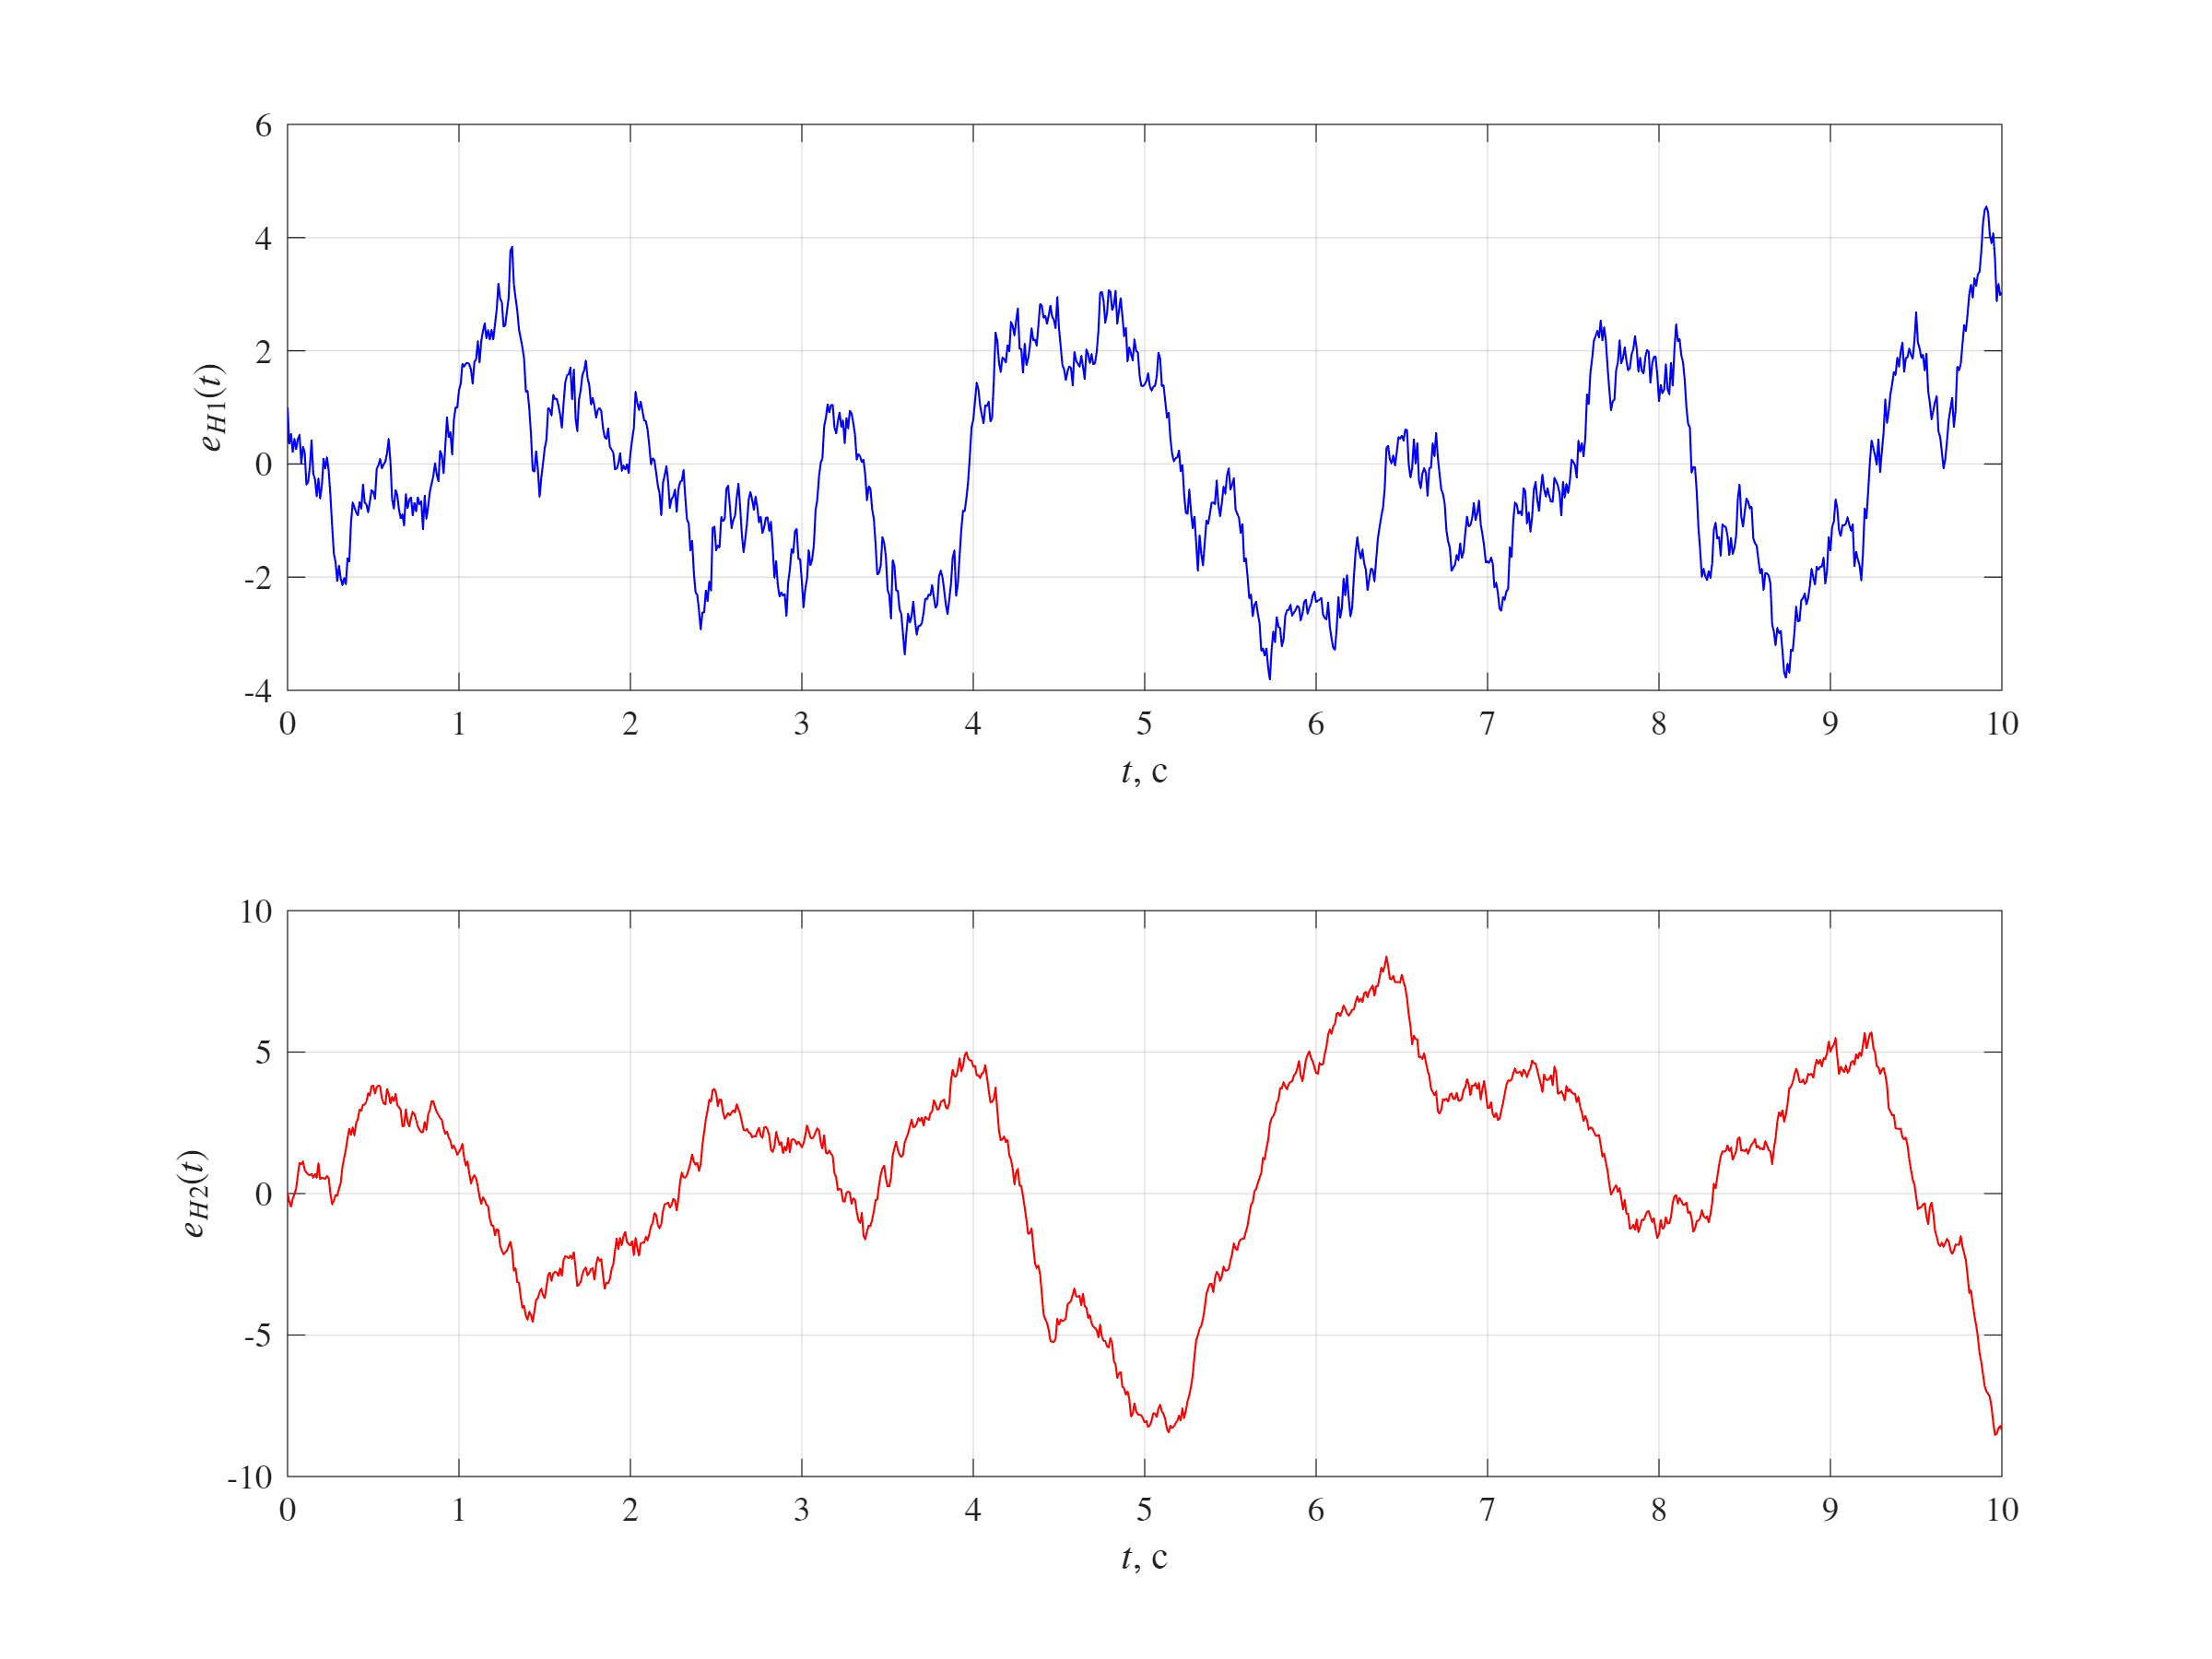

figure('Color', 'w', 'Position', [100 100 1200 900]);

subplot(2,1,1);
plot(t, e1, 'b', 'LineWidth', 0.8);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$e_{H1}(t)$', 'Interpreter', 'latex');
set(gca, 'FontSize', 14, 'TickLabelInterpreter', 'latex');

subplot(2,1,2);
plot(t, e2, 'r', 'LineWidth', 0.8);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$e_{H2}(t)$', 'Interpreter', 'latex');
set(gca, 'FontSize', 14, 'TickLabelInterpreter', 'latex');

exportgraphics(gcf, fullfile(folder, 'task5_errors.png'), 'Resolution', 600);

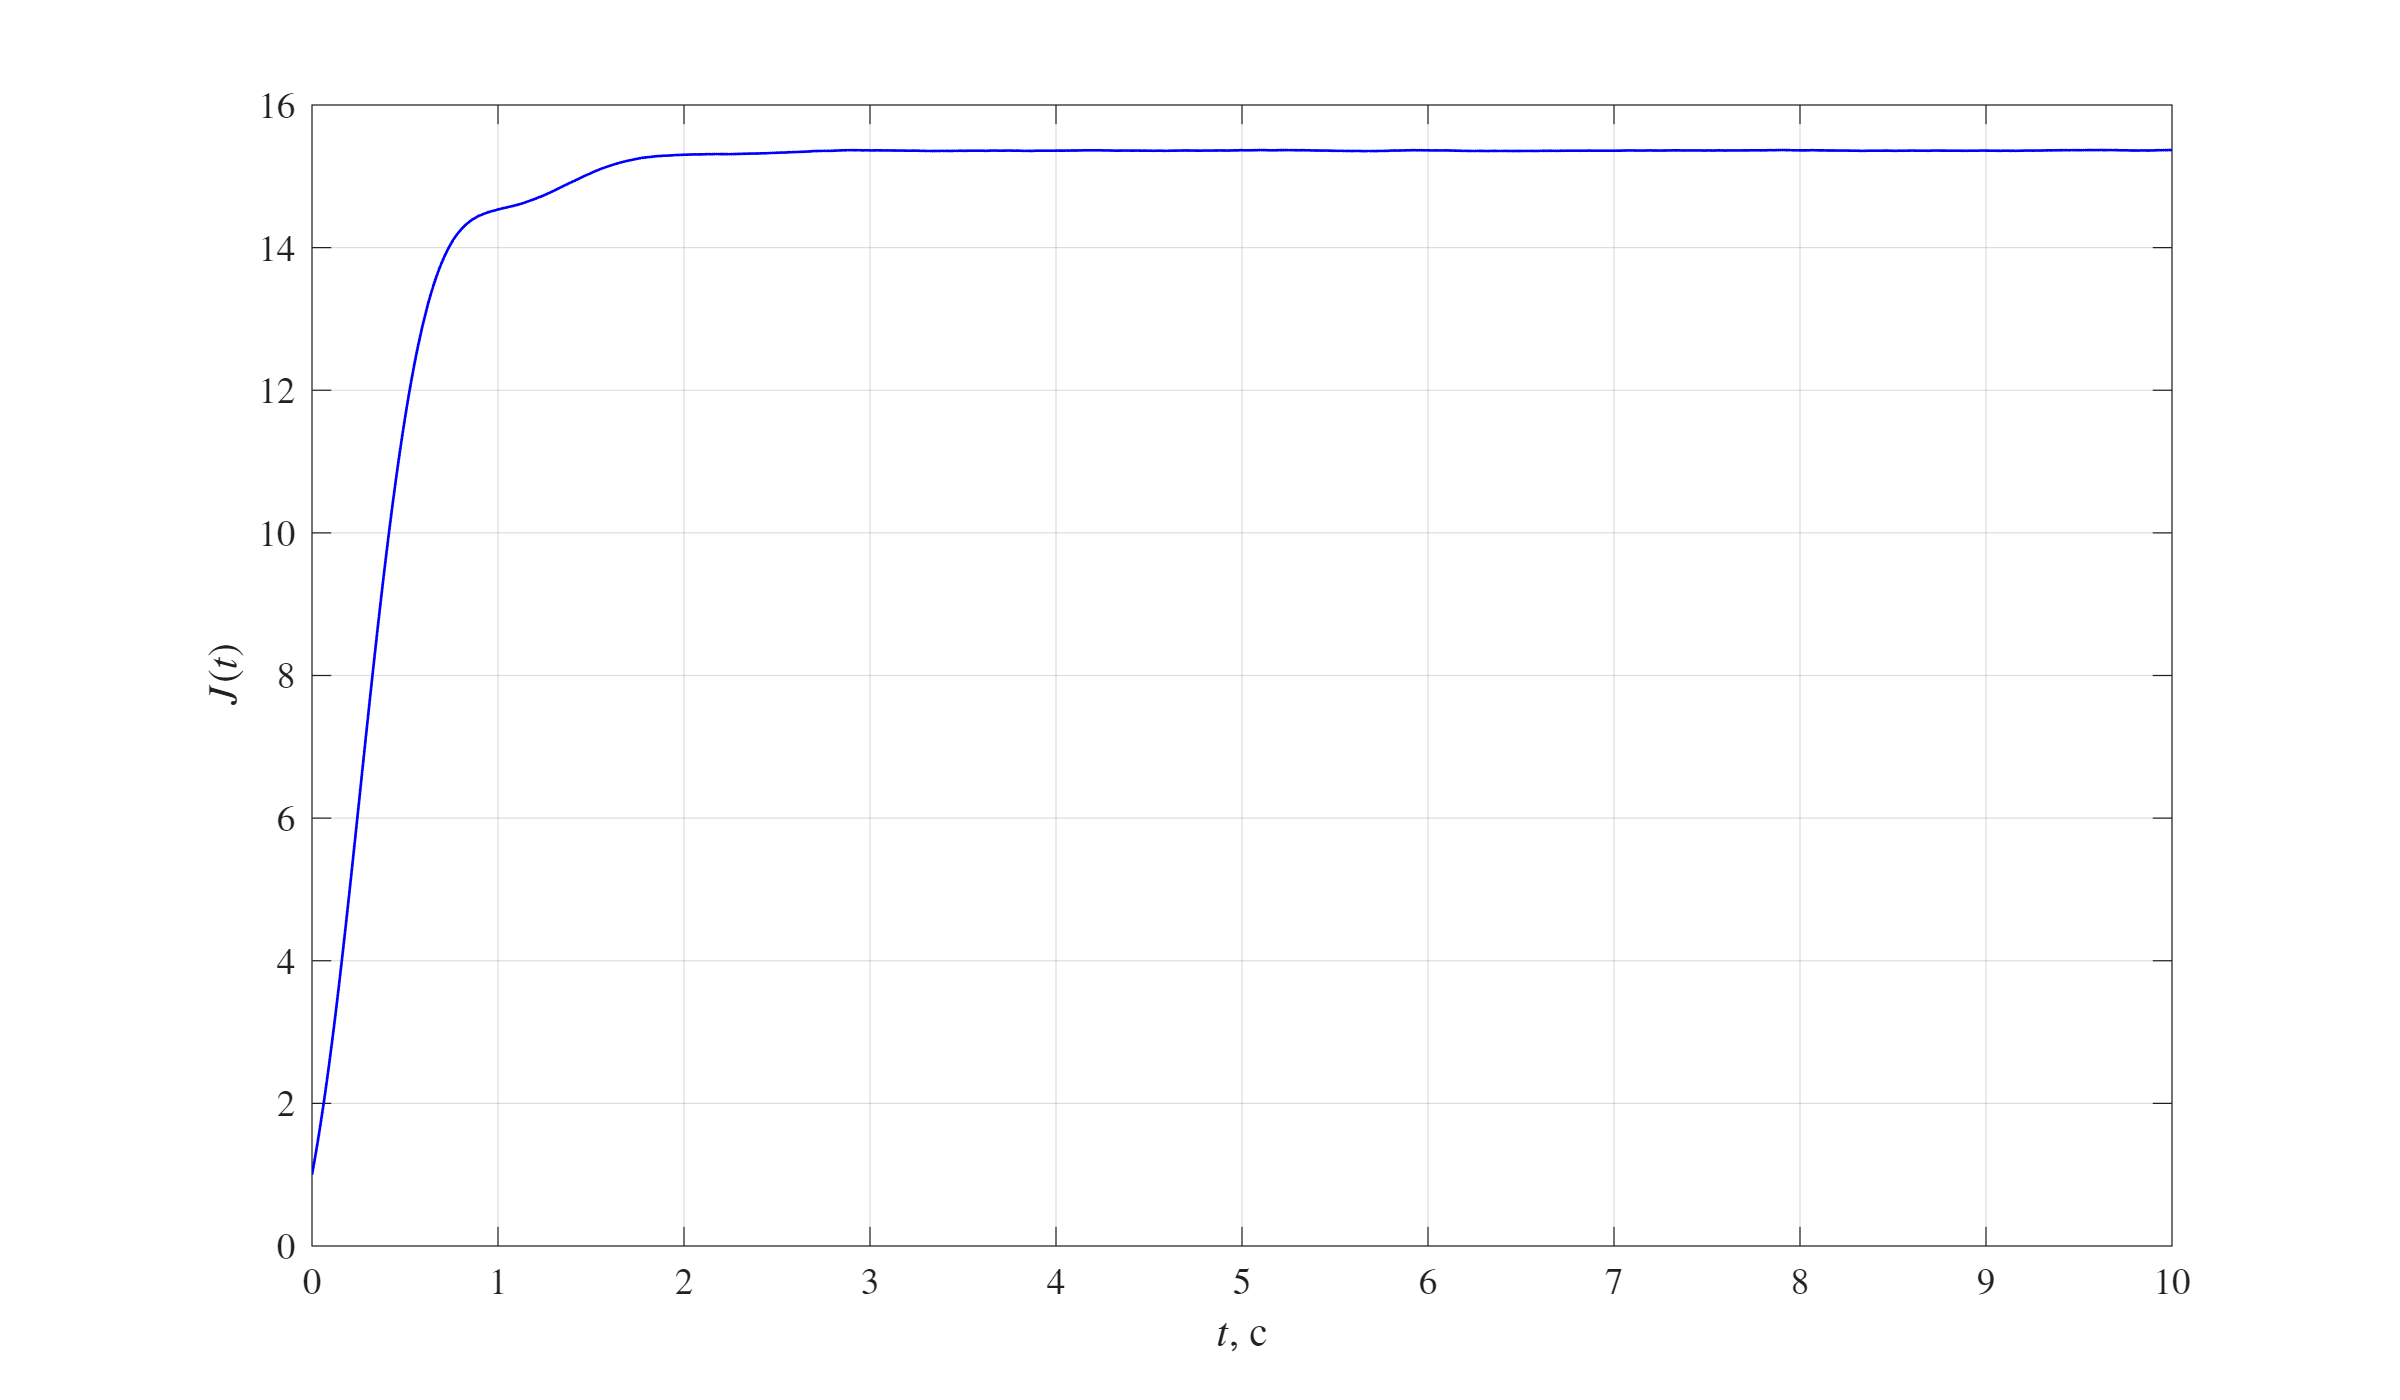

figure('Color', 'w', 'Position', [100 100 1200 700]);

plot(t, J, 'b', 'LineWidth', 1);
grid on;

xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$J(t)$', 'Interpreter', 'latex');
set(gca, 'FontSize', 14, 'TickLabelInterpreter', 'latex');

exportgraphics(gcf, fullfile(folder, 'task5_J.png'), 'Resolution', 600);

clear in out
delete(gcp('nocreate'));